## Set simulation config.

addpath("material-lookup/","functions/")
dt = 1e-3;
heat = 200; % W

## Set power switch thermal parameters.

% Angle for pyramid.
beta = 17; % °.

% Layer thicknesses in µm.
Lz = [175;...
      30;...
      800;...
      320;...
      800;...
      100;...
      4000]*1e-6;

% Heatsink parameters.
hs = [0.1; ... active Area m²
      0.05; ... Volume cooling liquid m³
      8]; ... flowrate l/min

% Initial conditions.
T0 = 45;
x0 = T0*ones(8,1);


## Create rth and cth values for cauer model.

[rth,cth] = cauer_mdl_pow_sw(beta,Lz,x0, hs);

## Create cauer model matrices and discretize for simulation.

% Generate state space system.
[A,B,C,D] = dss_cauer(rth,cth,dt);

## Generate sim input.

% Genearate signal for lsim.
t = dt:dt:100;
len = length(t);
xk = x0;
u = [heat;T0];
y = zeros(1,len);

for i=1:length(t)
    xk   = A*xk + B*u;
    y(i) = C*xk + D*u;
    [rth,cth] = cauer_mdl_pow_sw(beta,Lz,x0, hs);
    [A,B,C,D] = dss_cauer(rth,cth,dt);
end

## Plot outputs.

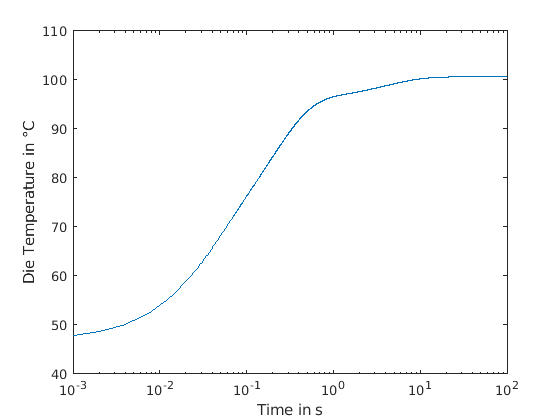

semilogx(t,y)
xlabel('Time in s');
ylabel('Die Temperature in °C')

rmpath("material-lookup/","functions/")